clear; close all;

% rplog=load('C:\Users\sgrc-325\Desktop\py\logger_RP_20240816_120849.csv');
% pclog=load('C:\Users\sgrc-325\Desktop\py\logger_PC_20240816_120852.csv');
pclog=load('C:\Users\sgrc-325\Desktop\py\log\logger_PC_20240830_133903_f.csv');


[n,~]=size(pclog);
rplog2=rplog;

Unrecognized function or variable 'rplog'.

rplog2(n+1:end,:)='';
miner=rplog2-pclog;
mean(miner)

t=pclog(:,1);
f(n,1)=zeros;
for i=1:n
    f(i)=i/t(i);
end
f(end)

ans = 5.0004

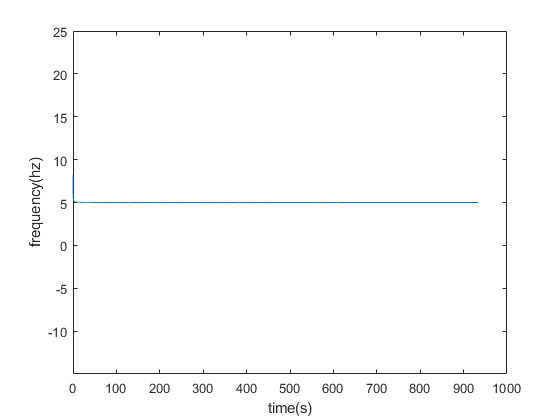

plot(t,f)
ylim([f(end)-20 f(end)+20])
xlabel('time(s)')
ylabel('frequency(hz)')

acc=pclog(:,3:5);
lat=pclog(:,6);
lon=pclog(:,7);
alt=pclog(:,8);
temp=pclog(:,10);
f=pclog(:,11);

% 算出直線距離

% 定義第一個點的經緯度
lat0 = 22.99748967; % 緯度
lon0 = 120.2216983; % 經度

d=zeros(n,1)

d =      0
     0
     0
     0
     0
     0
     0
     0
     0
     0


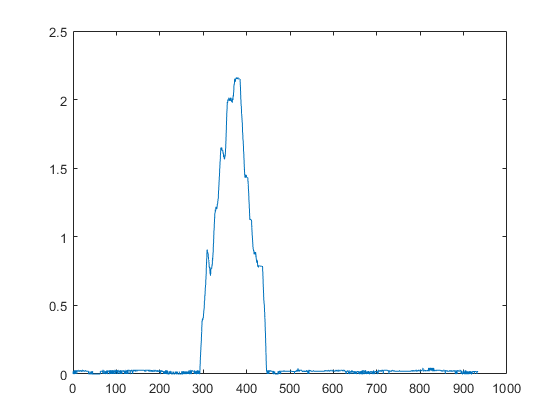

% 計算距離
for i=1:n
    d(i) = calculate_distance(lat0, lon0, lat(i), lon(i));
end

% 輸出結果
plot(t,d)

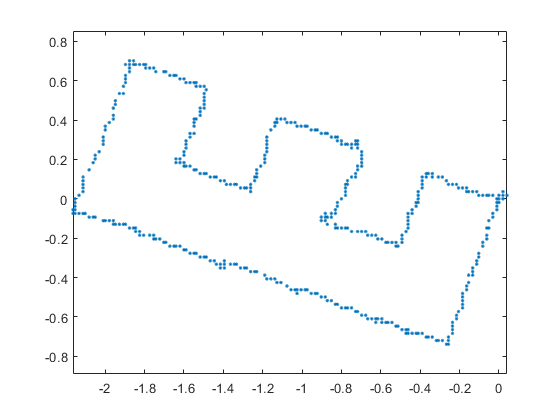

%經緯度轉成二度分帶座標

% 定義投影參數
central_meridian = 120.2216983; % 中心經度
latitude_of_origin = 22.99748967; % 基準緯度

% 創建 Transverse Mercator 投影
proj = defaultm('tranmerc'); % 使用橫軸墨卡托投影
proj.geoid = referenceEllipsoid('GRS 80'); % 使用 GRS 80 橢球體
proj.origin = [latitude_of_origin, central_meridian, 0]; % 設定基準緯度和中心經度
proj = defaultm(proj); % 更新投影參數


% 經緯度轉換
position = zeros(n, 2);
for i=1:n
    [position(i,1) position(i,2)]=mfwdtran(proj, lat(i), lon(i));
end

plot(position(:,1),position(:,2),'.')
axis equal

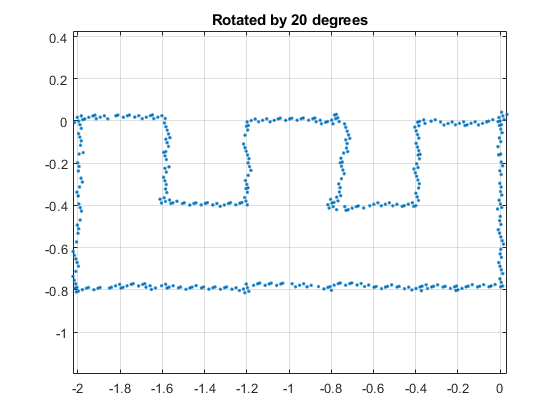

% 定義投影參數
central_meridian = 120.2216983; % 中心經度
latitude_of_origin = 22.99748967; % 基準緯度

% 創建橫軸墨卡托投影系統
proj = defaultm('tranmerc'); % 使用橫軸墨卡托投影
proj.geoid = referenceEllipsoid('GRS 80'); % 使用 GRS 80 橢球體
proj.origin = [latitude_of_origin, central_meridian, 0]; % 設定基準緯度和中心經度
proj = defaultm(proj); % 更新投影參數


% 確定經緯度數據的數量
n = length(lat);

% 初始化位置矩陣，n 行 2 列的矩陣
position = zeros(n, 2);

% 進行經緯度轉換
for i = 1:n
    [position(i, 1), position(i, 2)] = mfwdtran(proj, lat(i), lon(i));
end

% 定義旋轉角度（以度為單位）
angle = 20; % 假設旋轉45度
theta = deg2rad(angle); % 將角度轉換為弧度

% 生成旋轉矩陣
rotation_matrix = [cos(theta), -sin(theta); sin(theta), cos(theta)];

% 對 position 矩陣中的所有點進行旋轉
rotated_position = (rotation_matrix * position')';

% 繪製旋轉後的點集
figure;
plot(rotated_position(:,1), rotated_position(:,2), '.');
axis equal;
title(sprintf('Rotated by %d degrees', angle));
grid on